fis = readfis('../models/CS_Expert');
T = readtable('../data/cs-test.csv');
x_test = T{:,{'Age','Income','PastDue'}};
y_test = T{:,'Default'};

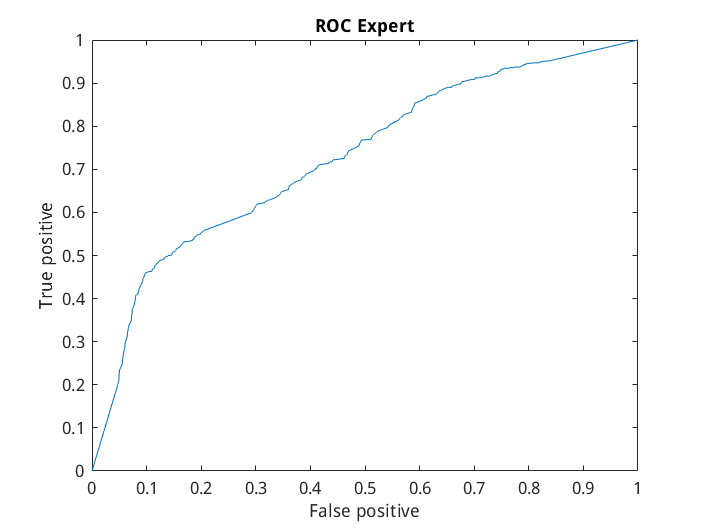


y_pred = evalfis(fis, x_test);
[X,Y,T,AUC] = perfcurve(y_test,y_pred,1);
plot(X,Y)
xlabel('False positive') 
ylabel('True positive')
title('ROC Expert')

AUC

AUC = 0.7265

fis = readfis('../models/CS_NN');

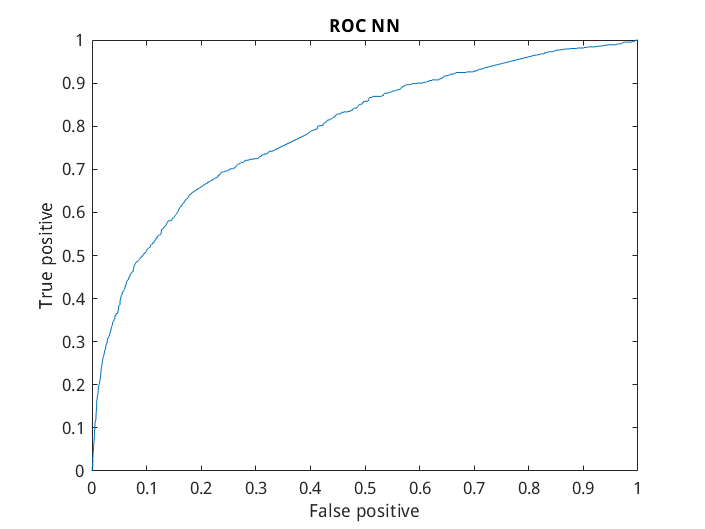

y_pred = evalfis(fis, x_test);
[X,Y,T,AUC] = perfcurve(y_test,y_pred,1);
plot(X,Y)
xlabel('False positive') 
ylabel('True positive')
title('ROC NN')

AUC

AUC = 0.7931